# Test NN.m

## Parameters

x                                      = -5:0.2:5;
y                                      = sin(x) + 0.1 * randn(size(x));
layers                                 = [30, 30, 1];

number_of_epochs                       = 1000;
learning_rate                          = 0.01;
number_of_validations_faild            = 6;

cost_function                          = @NN.quadratic_cost_function;
diff_cost_function                     = @NN.diff_quadratic_cost_function;
activation_function                    = @NN.tanh_activation_function;
diff_activation_function               = @NN.diff_tanh_activation_function;
activation_function_of_last_layer      = @NN.line_activation_function;
diff_activation_function_of_last_layer = @NN.diff_line_activation_function;

delay                                  = 0.1;

## Neural Network

nn = NN(x, y, layers);

nn.number_of_epochs = number_of_epochs;
nn.learning_rate = learning_rate;
nn.number_of_validations_faild = number_of_validations_faild;

nn.C = cost_function;
nn.C_ = diff_cost_function;
nn.s = activation_function;
nn.s_ = diff_activation_function;
nn.sL = activation_function_of_last_layer;
nn.sL_ = diff_activation_function_of_last_layer;

nn.run();

## Show Results

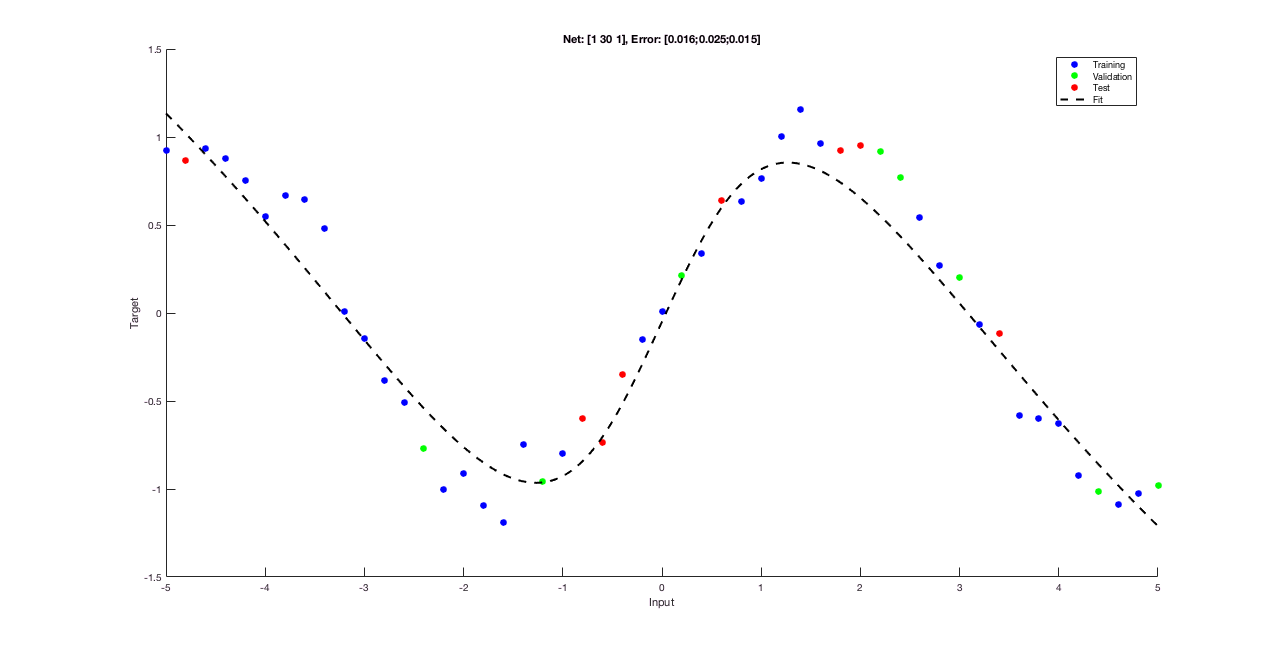

nn.plot_fit();

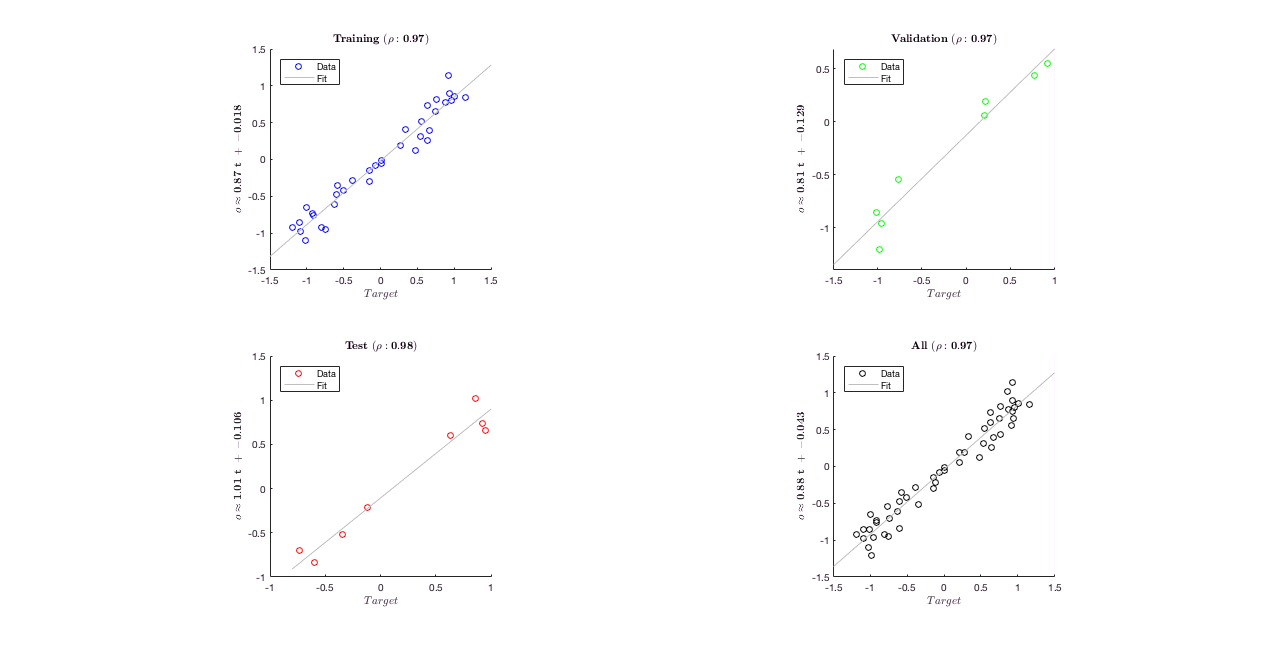

nn.plot_all_regressions();

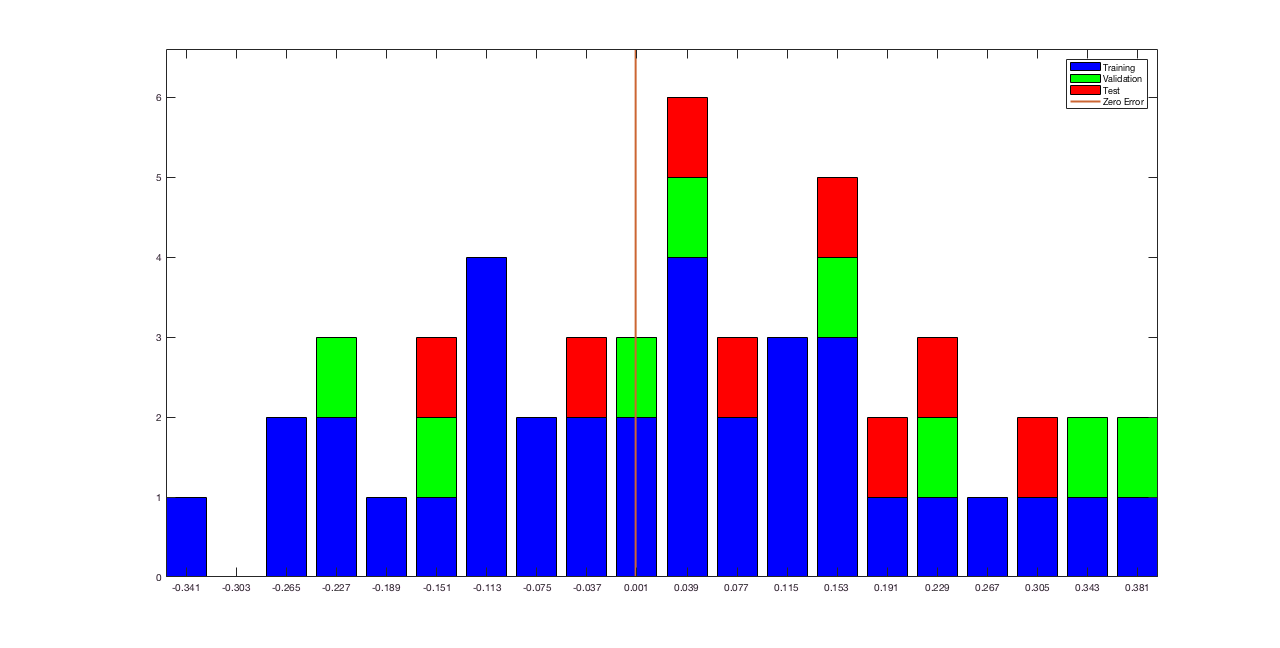

nn.plot_error_histogram();

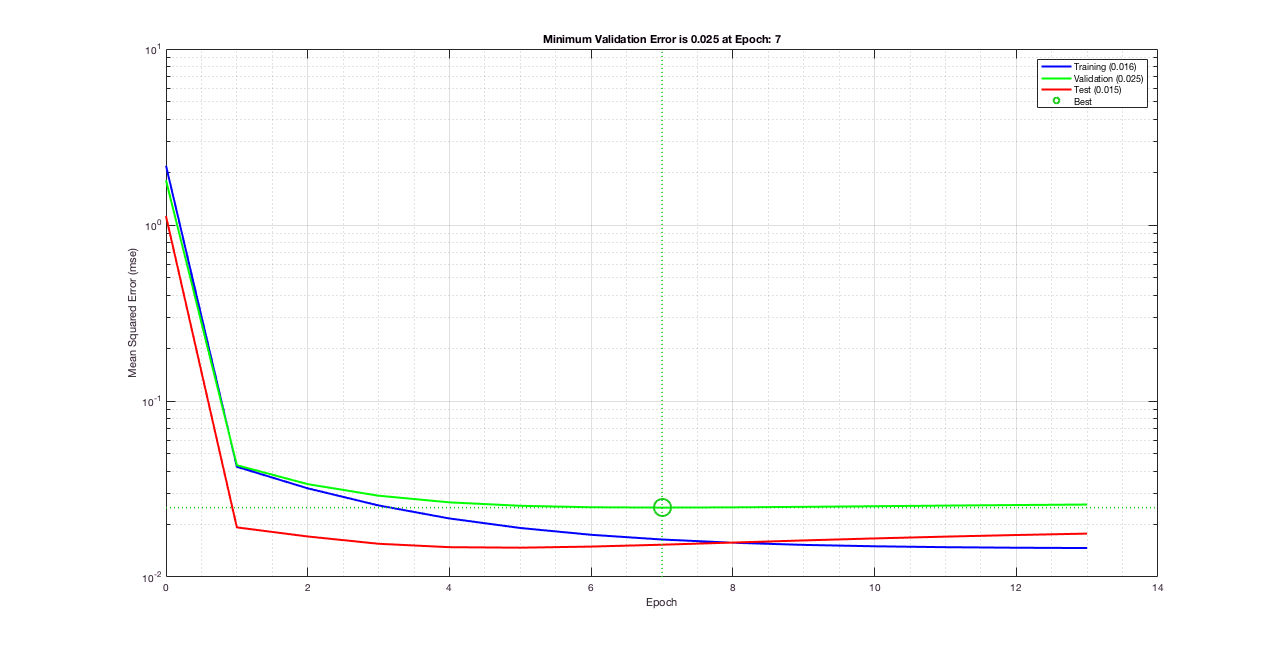

nn.plot_total_cost_history();

% nn.animate_fit_history(delay)